## １：500 kHzの場合

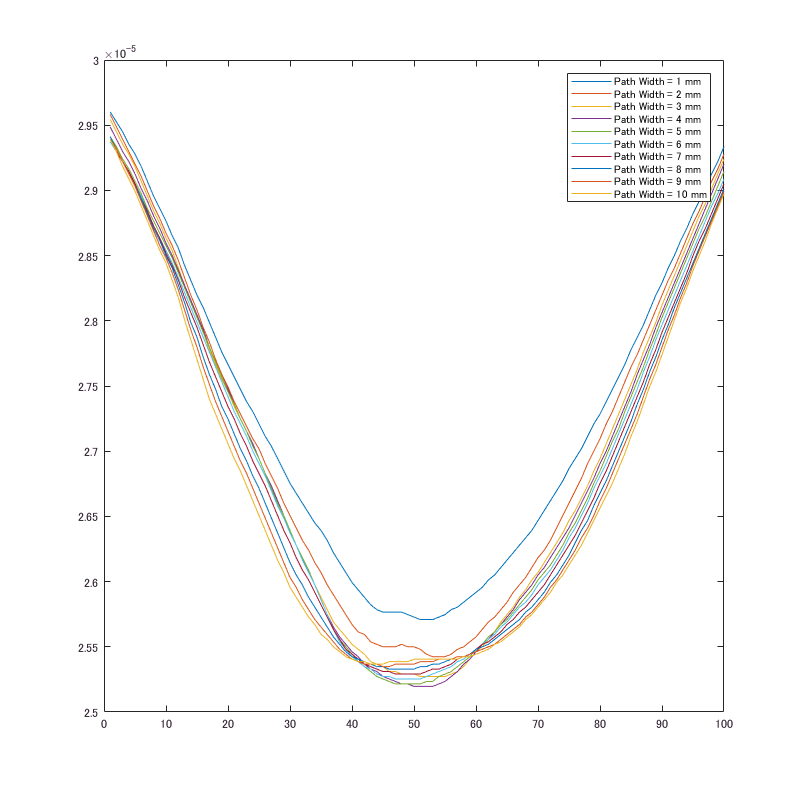

load("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/tof_cell.mat")
legendInfo = cell(1,10);
figure;
for ii = 1:10
    plot(tof_cell(101:200,1,ii));
    hold on
    legendInfo{ii} = sprintf('Path Width = %d mm',ii);
end
legend(legendInfo);
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/tof_various_path_width_500kHz",'png',[800,800]);

## 2：2 MHzの場合

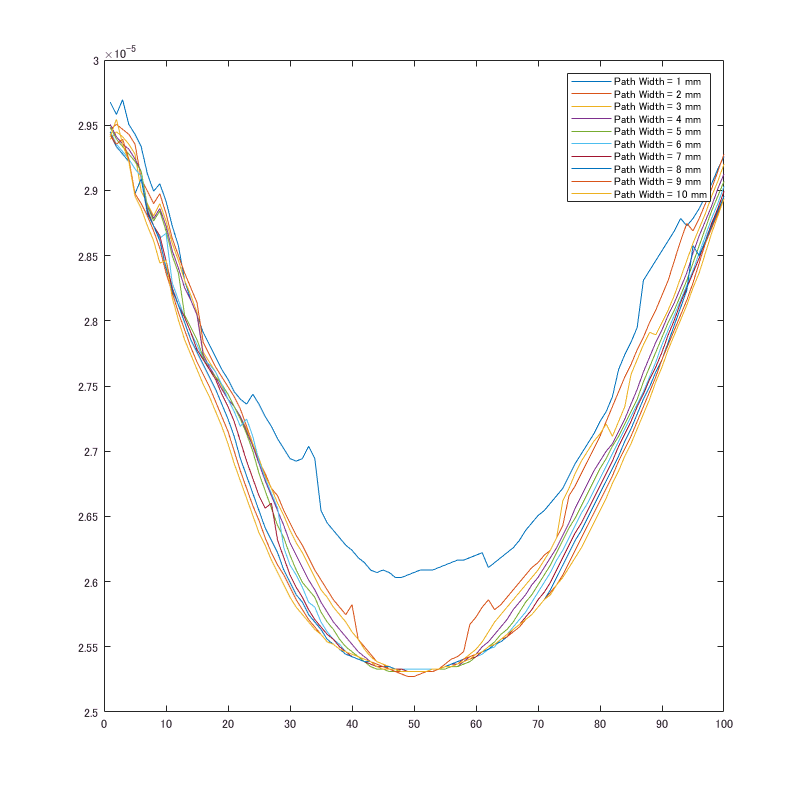

load("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/tof_cell_frq2e6.mat")
figure;
for ii = 1:10
    plot(tof_cell(101:200,1,ii));
    hold on
    legendInfo{ii} = sprintf('Path Width = %d mm',ii);
end
legend(legendInfo);
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/tof_various_path_width_2MHz",'png',[800,800]);

## ３：媒質（case8）について，中央部に1,2,...,10 mmの間隙，間隙中に0.0, 2.5, ..., 10.0 %のEMCL領域を設けた．

## これを500 kHz, 2 MHzに分けてシミュレーションを行った．これらすべてのデータを可視化したい．

・dim

tof_cell(受信素子数，送信素子数，間隙幅数，間隙中のEMCL領域数)

・1,2ですでに間隙幅を変えて変動をみたので，今回は間隙中のEMCL占有率を変えて変動を見てみる

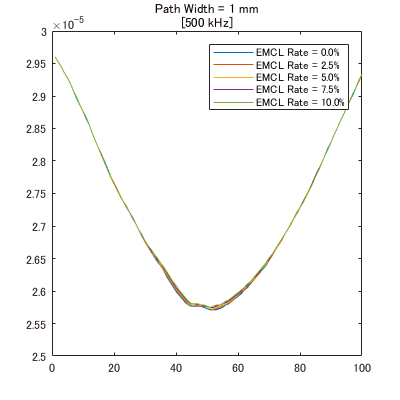

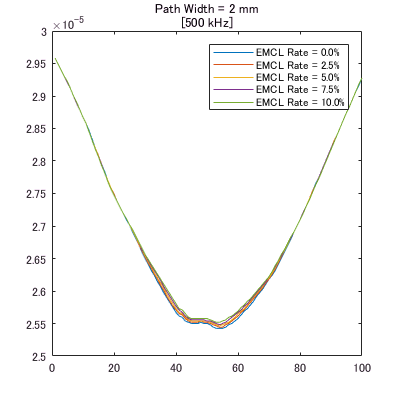

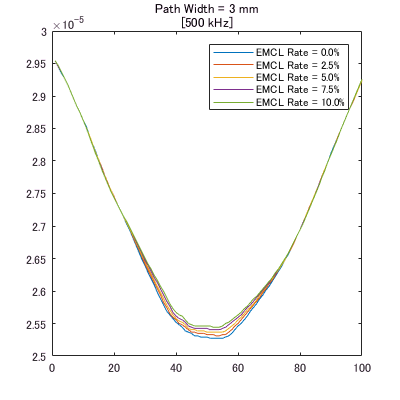

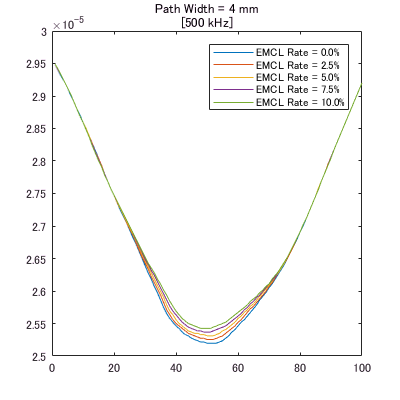

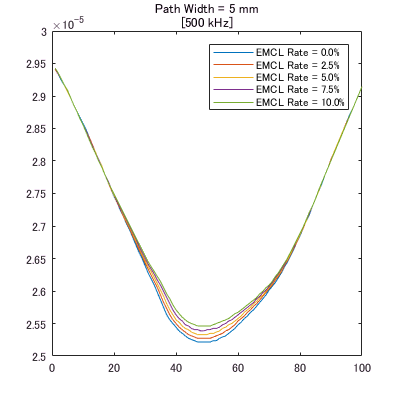

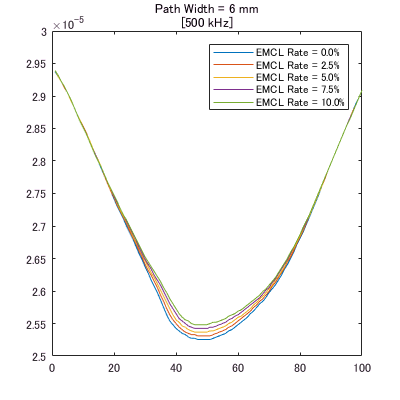

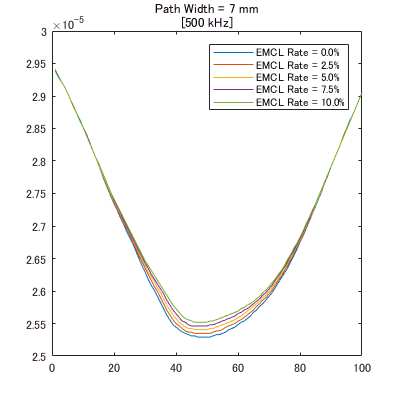

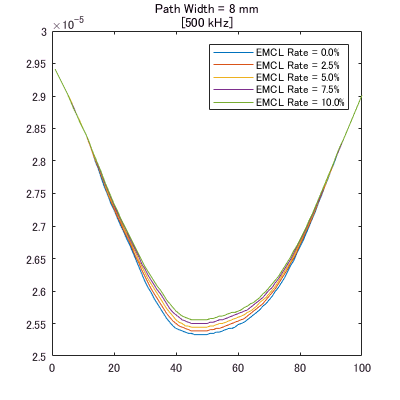

load("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/tof_cell_frq500kHz.mat")
for jj = 1:10
    figure;
    legendInfo = cell(1,5);
    for ii = 1:5
        plot(tof_cell(101:200,1,jj,ii));
        hold on
        legendInfo{ii} = sprintf('EMCL Rate = %0.1f%%',(ii-1)*2.5);
    end
    hold off
    ylim([2.5e-5 3e-5])
    legend(legendInfo);
    titlename = sprintf('Path Width = %d mm',jj);
    title({titlename;'[500 kHz]'});
    savefilename = sprintf('H:/result/2018_10_18_analyze_IMCLpath_variousSize/500kHz_Path Width%dmm',jj);
    exportfig(savefilename,'png',[400,400]);
end

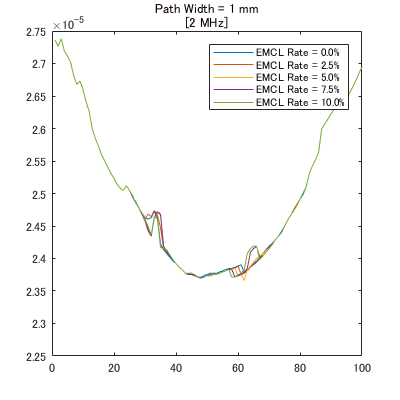

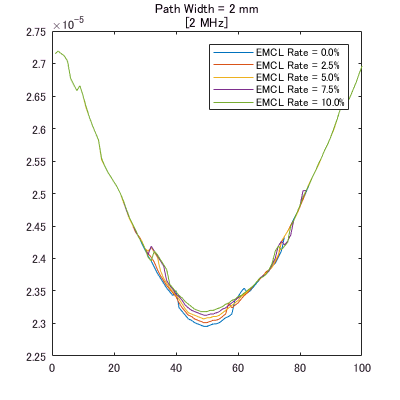

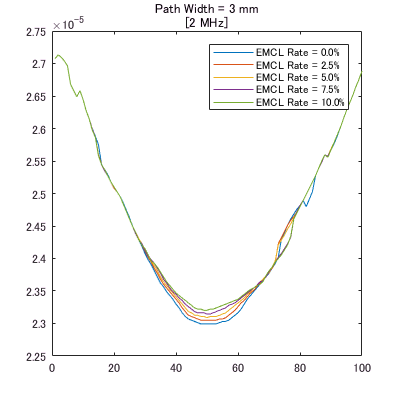

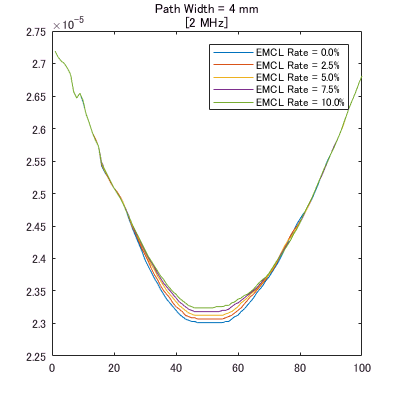

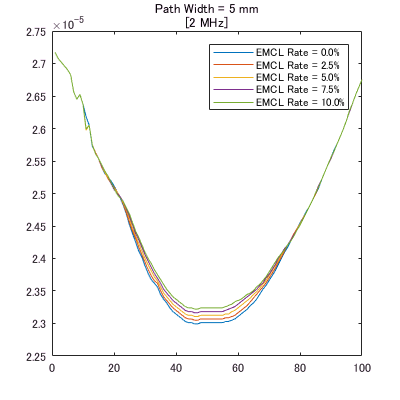

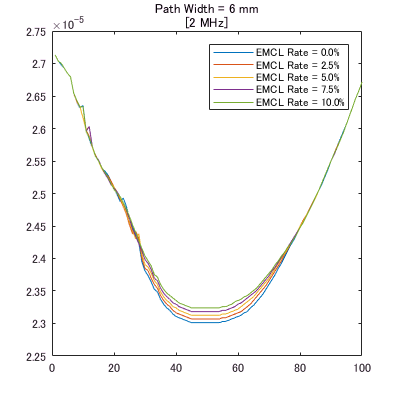

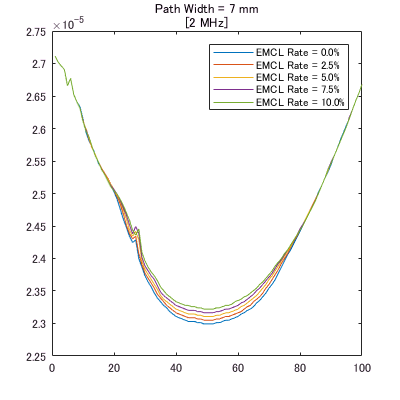

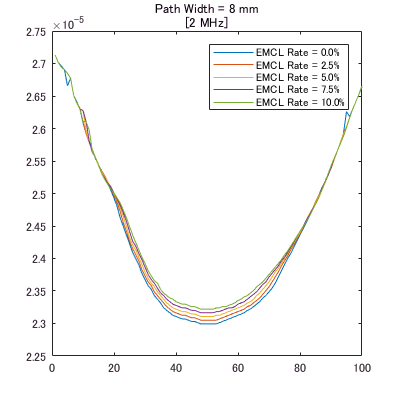

load("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/tof_cell_frq2MHz.mat")
for jj = 1:10
    figure;
    legendInfo = cell(1,5);
    for ii = 1:5
        plot(tof_cell(101:200,1,jj,ii));
        hold on
        legendInfo{ii} = sprintf('EMCL Rate = %0.1f%%',(ii-1)*2.5);
    end
    hold off
    ylim([2.25e-5 2.75e-5])
    legend(legendInfo);
    titlename = sprintf('Path Width = %d mm',jj);
    title({titlename;'[2 MHz]'});
    savefilename = sprintf('H:/result/2018_10_18_analyze_IMCLpath_variousSize/2MHz_Path Width%dmm',jj);
    exportfig(savefilename,'png',[400,400]);
end

・2 MHzでは間隙幅が2 mm以降から到達時間が著しく短縮され，間隙中のEMCL占有率にともなう到達時間の変動も確認できる様になった．

・500 kHzでは間隙幅が 2mm以降から到達時間の短縮がみられ，間隙中のEMCL占有率変化にともなう到達時間の変動も，2 MHzの場合ほど顕著ではないが確認できるようになった．

## ３－２：[RFデータに着目]

## 媒質（case8）について，中央部に1,2,...,10 mmの間隙，間隙中に0.0, 2.5, ..., 10.0 %のEMCL領域を設けた．

## これを500 kHz, 2 MHzに分けてシミュレーションを行った．これらすべてのデータを可視化したい．

・RFデータの場合も３と同様に，

①間隙中のEMCL占有率を固定（0 %）して間隙幅を変えた場合

②間隙幅を固定して間隙中のEMCL占有率を変えた場合

の２パターンの可視化を行う．受信素子は対向する素子であるch50に着目する．

## ①

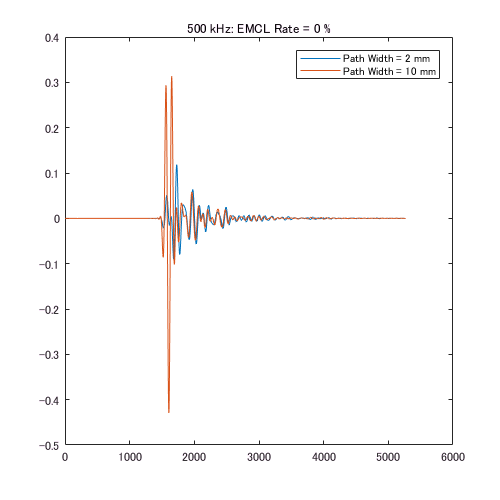

legendInfo = cell(1,2);
figure;
for ii = 2:8:10
    loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_0.0%%/rfdata.mat",ii);
    load(loadfilename);
    plot(rfdata(:,150));
    hold on
    legendInfo{ceil(ii/8)} = sprintf('Path Width = %d mm',ii);
end
legend(legendInfo);
title('500 kHz: EMCL Rate = 0 %')
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/500kHz_RFsignal_various_path_width",'png',[500,500]);

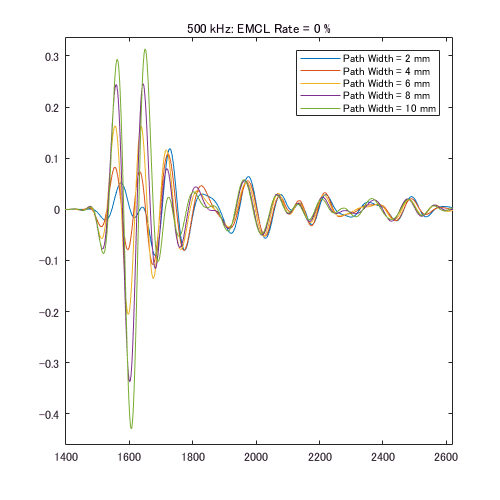

legendInfo2 = cell(1,5);
figure;
for ii = 2:2:10
    loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_0.0%%/rfdata.mat",ii);
    load(loadfilename);
    plot(rfdata(:,150));
    hold on
    legendInfo2{round(ii/2)} = sprintf('Path Width = %d mm',ii);
end
title('500 kHz: EMCL Rate = 0 %')
legend(legendInfo2);
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/500kHz_RFsignal_various_path_width2",'png',[500,500]);
xlim([1002 2144])
ylim([-0.281 0.336])
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/500kHz_RFsignal_various_path_width3",'png',[500,500]);
xlim([1397 2621])
ylim([-0.461 0.337])
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/500kHz_RFsignal_various_path_width4",'png',[500,500]);

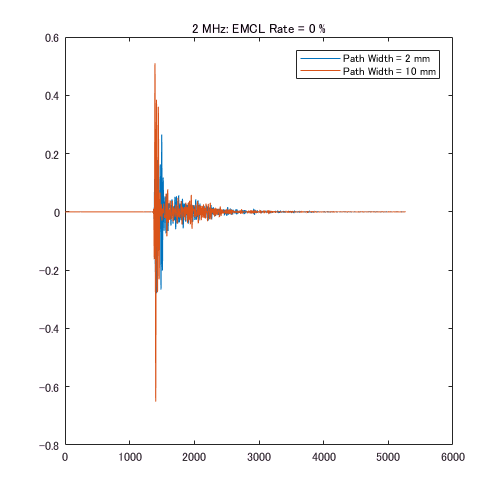

legendInfo = cell(1,2);
figure;
for ii = 2:8:10
    loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_0.0%%_2MHz/rfdata.mat",ii);
    load(loadfilename);
    plot(rfdata(:,150));
    hold on
    legendInfo{ceil(ii/8)} = sprintf('Path Width = %d mm',ii);
end
legend(legendInfo);
title('2 MHz: EMCL Rate = 0 %')
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/2MHz_RFsignal_various_path_width",'png',[500,500]);

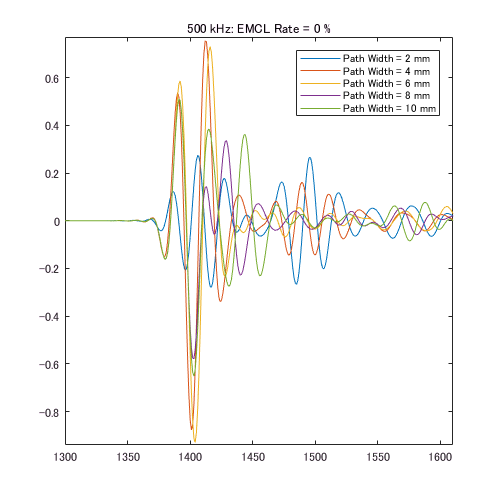

legendInfo2 = cell(1,5);
figure;
for ii = 2:2:10
    loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_0.0%%_2MHz/rfdata.mat",ii);
    load(loadfilename);
    plot(rfdata(:,150));
    hold on
    legendInfo2{round(ii/2)} = sprintf('Path Width = %d mm',ii);
end
title('500 kHz: EMCL Rate = 0 %')
legend(legendInfo2);
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/2MHz_RFsignal_various_path_width2",'png',[500,500]);
xlim([1300 1610])
ylim([-0.94 0.77])
exportfig("H:/result/2018_10_18_analyze_IMCLpath_variousSize/2MHz_RFsignal_various_path_width3",'png',[500,500]);

## ②

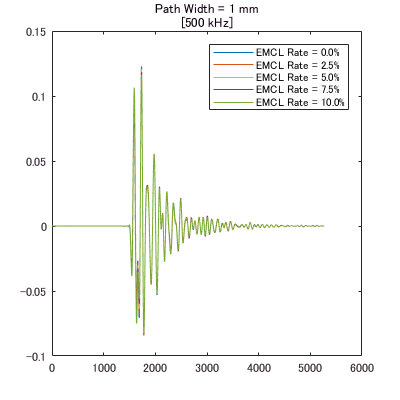

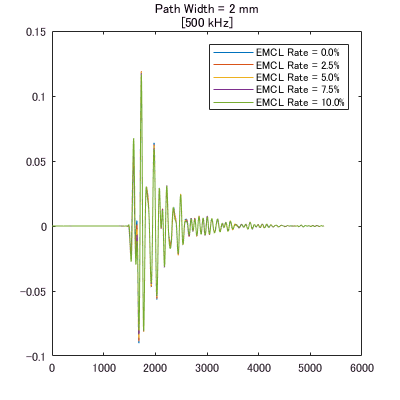

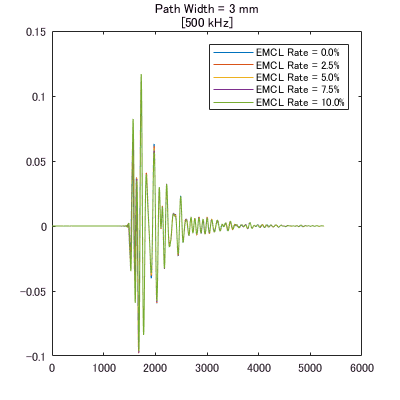

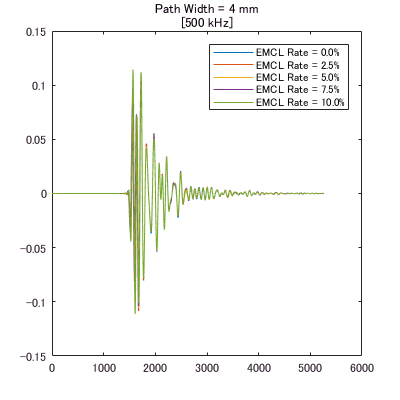

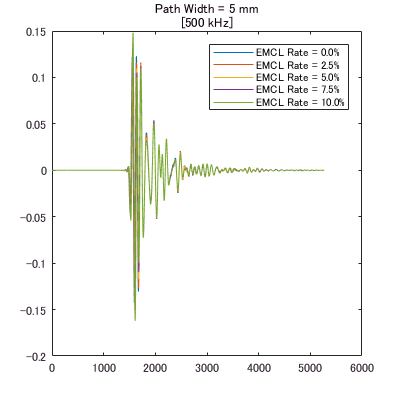

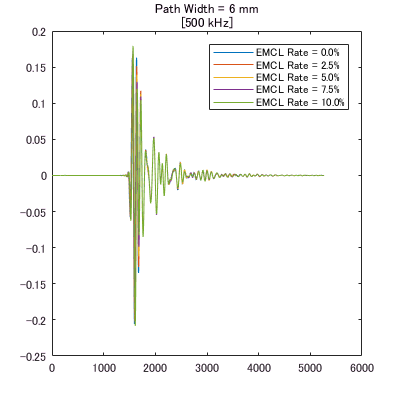

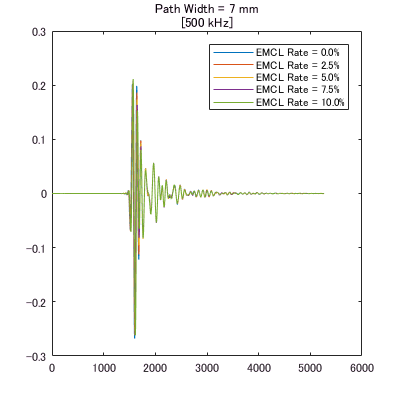

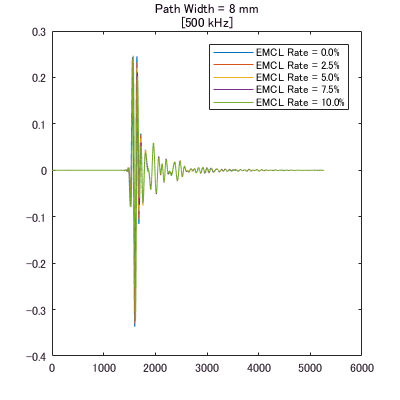

for jj = 1:10
    figure;
    legendInfo = cell(1,5);
    for ii = 1:5
        loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_%0.1f%%/rfdata.mat",jj,(ii-1)*2.5);
        load(loadfilename);
        plot(rfdata(:,150));
        hold on
        legendInfo{ii} = sprintf('EMCL Rate = %0.1f%%',(ii-1)*2.5);
    end
    hold off
    legend(legendInfo);
    titlename = sprintf('Path Width = %d mm',jj);
    title({titlename;'[500 kHz]'});
    ylim([-0.15 0.15])
    savefilename = sprintf('H:/result/2018_10_18_analyze_IMCLpath_variousSize/500kHz_Path Width%dmm_rfsignal',jj);
    exportfig(savefilename,'png',[400,400]);
end

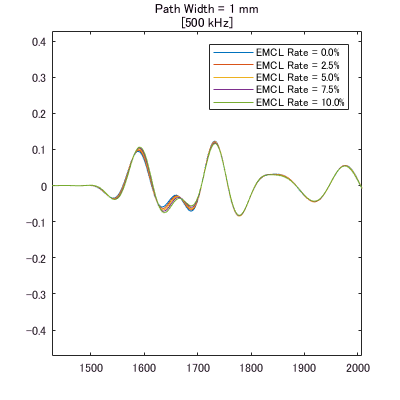

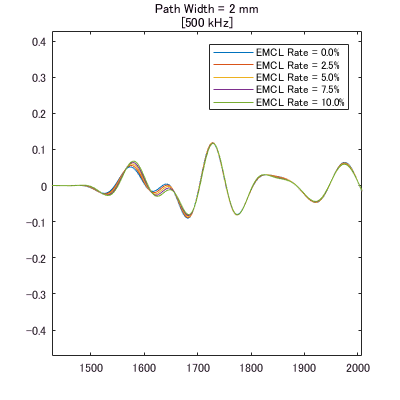

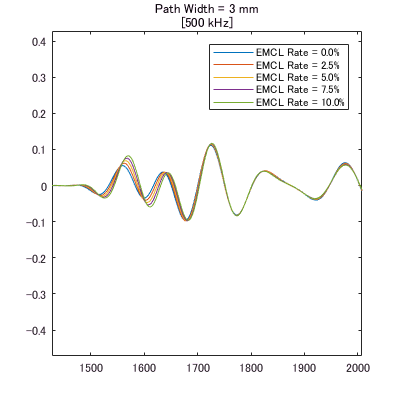

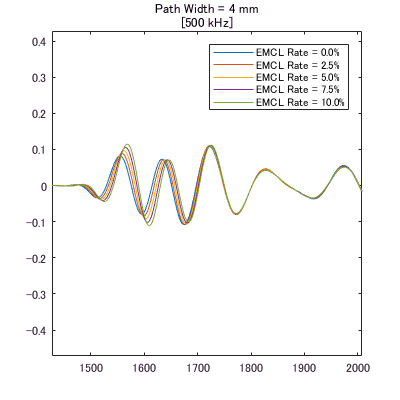

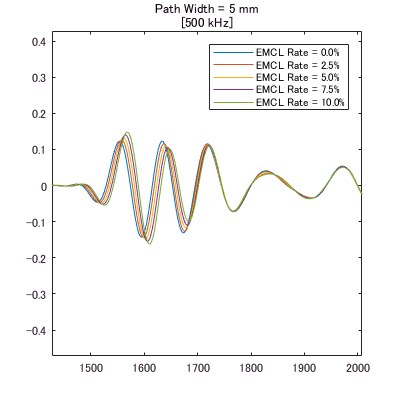

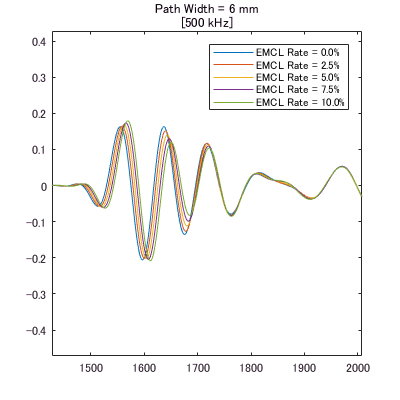

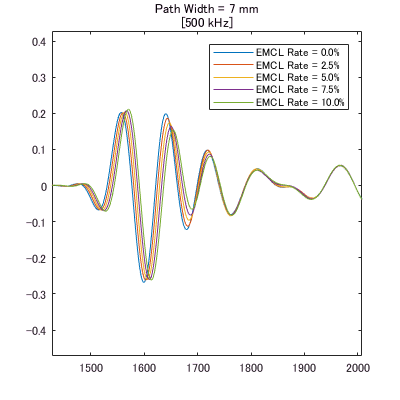

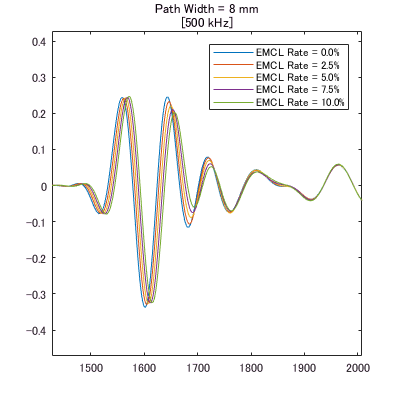

for jj = 1:10
    figure;
    legendInfo = cell(1,5);
    for ii = 1:5
        loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_%0.1f%%/rfdata.mat",jj,(ii-1)*2.5);
        load(loadfilename);
        plot(rfdata(:,150));
        hold on
        legendInfo{ii} = sprintf('EMCL Rate = %0.1f%%',(ii-1)*2.5);
    end
    hold off
    legend(legendInfo);
    titlename = sprintf('Path Width = %d mm',jj);
    title({titlename;'[500 kHz]'});
    xlim([1427 2008])
    ylim([-0.472 0.428])
    savefilename = sprintf('H:/result/2018_10_18_analyze_IMCLpath_variousSize/500kHz_Path Width%dmm_rfsignal_detail',jj);
    exportfig(savefilename,'png',[400,400]);
end

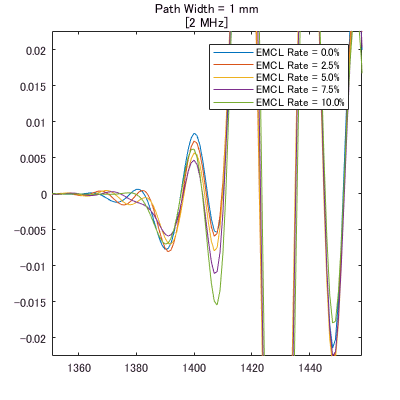

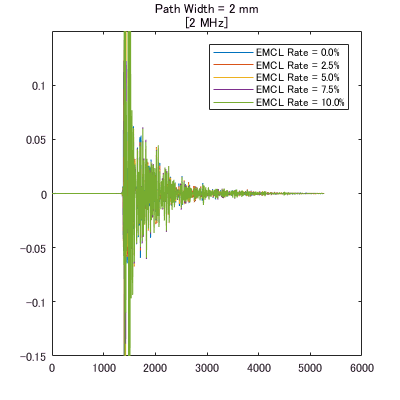

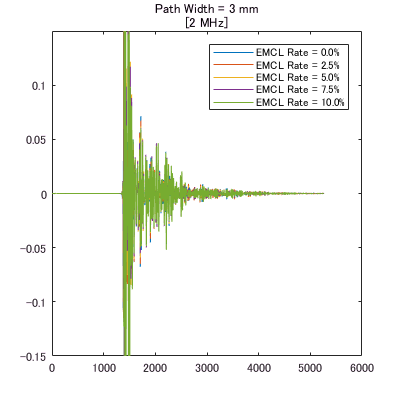

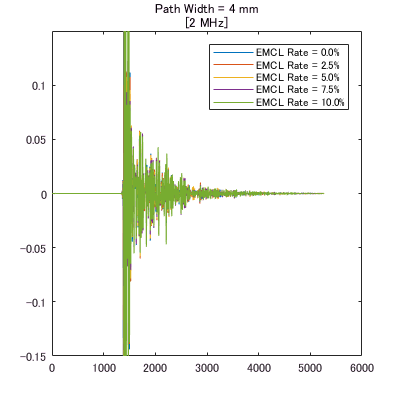

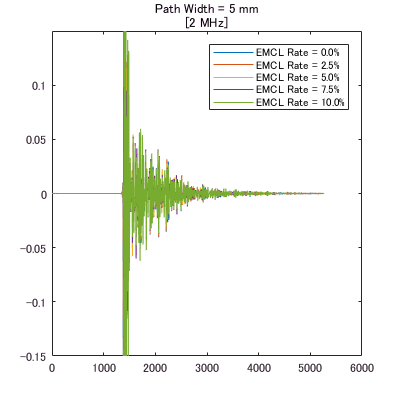

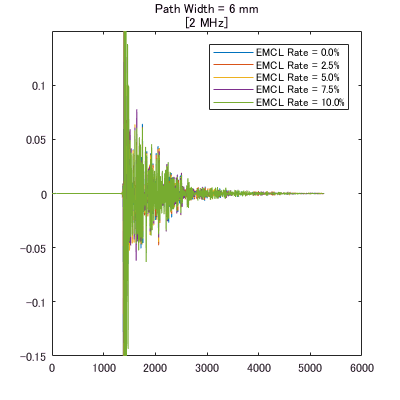

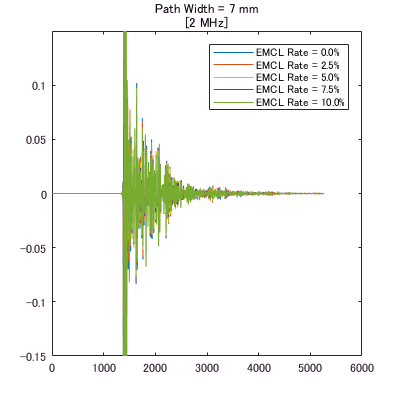

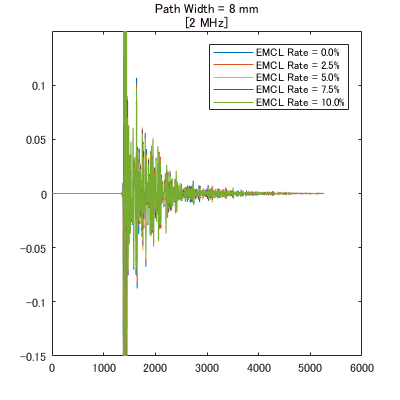

for jj = 1:10
    figure;
    legendInfo = cell(1,5);
    for ii = 1:5
        loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_%0.1f%%_2MHz/rfdata.mat",jj,(ii-1)*2.5);
        load(loadfilename);
        plot(rfdata(:,150));
        hold on
        legendInfo{ii} = sprintf('EMCL Rate = %0.1f%%',(ii-1)*2.5);
    end
    hold off
    legend(legendInfo);
    titlename = sprintf('Path Width = %d mm',jj);
    title({titlename;'[2 MHz]'});
    ylim([-0.15 0.15])
    savefilename = sprintf('H:/result/2018_10_18_analyze_IMCLpath_variousSize/2MHz_Path Width%dmm_rfsignal',jj);
    exportfig(savefilename,'png',[400,400]);
end

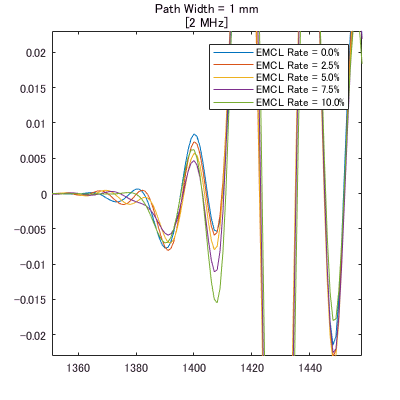

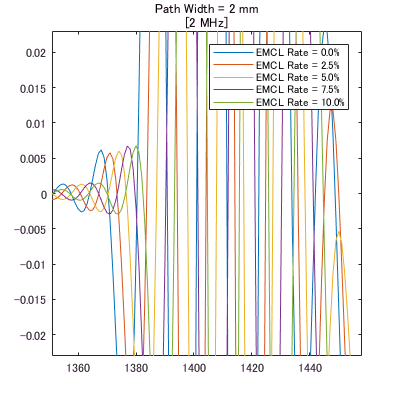

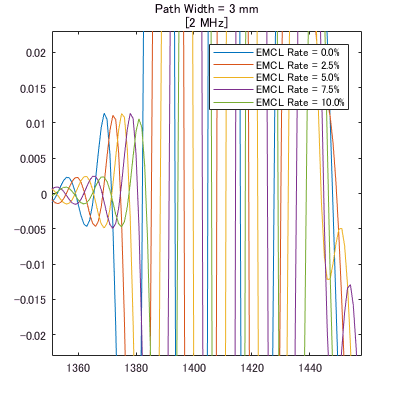

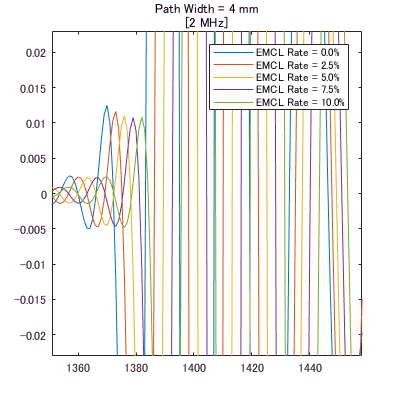

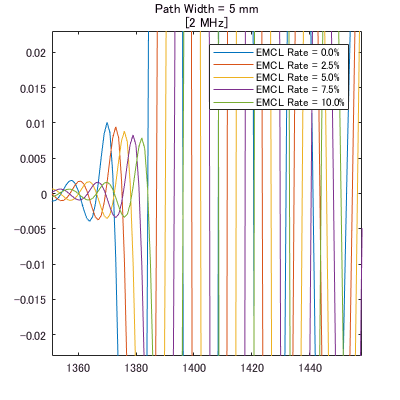

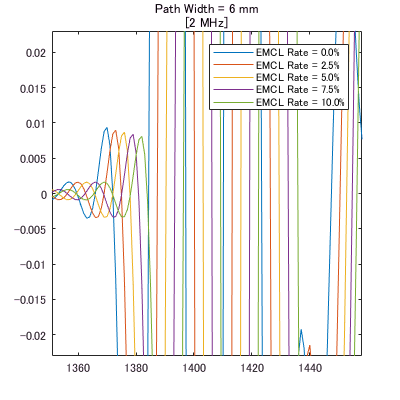

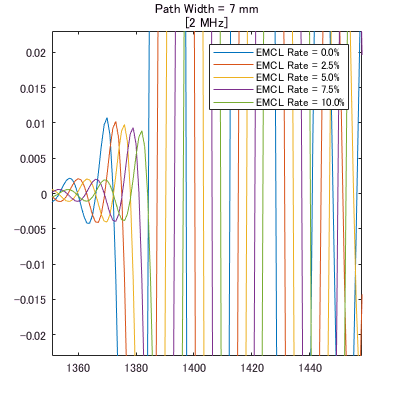

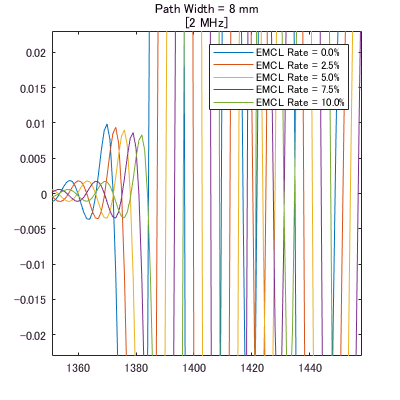

for jj = 1:10
    figure;
    legendInfo = cell(1,5);
    for ii = 1:5
        loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_%0.1f%%_2MHz/rfdata.mat",jj,(ii-1)*2.5);
        load(loadfilename);
        plot(rfdata(:,150));
        hold on
        legendInfo{ii} = sprintf('EMCL Rate = %0.1f%%',(ii-1)*2.5);
    end
    hold off
    legend(legendInfo);
    titlename = sprintf('Path Width = %d mm',jj);
    title({titlename;'[2 MHz]'});
    xlim([1351 1458])
    ylim([-0.023 0.023])
    savefilename = sprintf('H:/result/2018_10_18_analyze_IMCLpath_variousSize/2MHz_Path Width%dmm_rfsignal_detail',jj);
    exportfig(savefilename,'png',[400,400]);
end

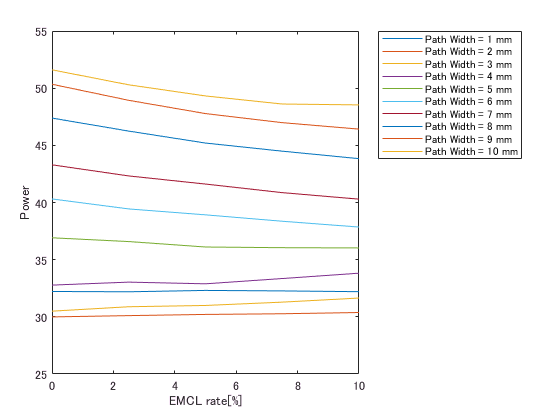

figure;
total_amp = zeros(10,5);
for jj = 1:10
    for ii = 1:5
        loadfilename = sprintf("H:/data/kwave/result/2018_10_18_IMCLpath_variousSize/case8_IMCL_width_%dmm_void_%0.1f%%/rfdata.mat",jj,(ii-1)*2.5);
        load(loadfilename);
        total_amp(jj,ii) = sum(abs(rfdata(:,150)));
    end
end
legendInfo = cell(1,10);
for jj = 1:10
    plot(0:2.5:10.0,total_amp(jj,:));
    legendInfo{jj} = sprintf('Path Width = %d mm',jj);
    hold on
end
legend(legendInfo,'Location','bestoutside');
xlabel('EMCL rate[%]')
ylabel('Power')